# Transform Testing

R = (imread('data/calibrated_raw/20250321T192416_651_StackInput.tiff'));
I = (imread('data/calibrated_raw/20250321T193124_660_StackInput.tiff'));

Get points

r_points = get_star_tracking_points(R);
i_points = get_star_tracking_points(I);

[r_points, i_points] = match_points(r_points, i_points);

Extract features

% Estimate geometric transformation
tform = estimateGeometricTransform2D(i_points, r_points, 'affine');

Warp

outputView = imref2d(size(R));
aligned = imwarp(I, tform, 'OutputView', outputView);

Alignment

% apply transformation to moving points
movingPointsTransformed = transformPointsForward(tform, i_points);

% visualize
figure;
i = imadjust(im2double(rgb2gray(R)), [0, .2]), [];

i =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

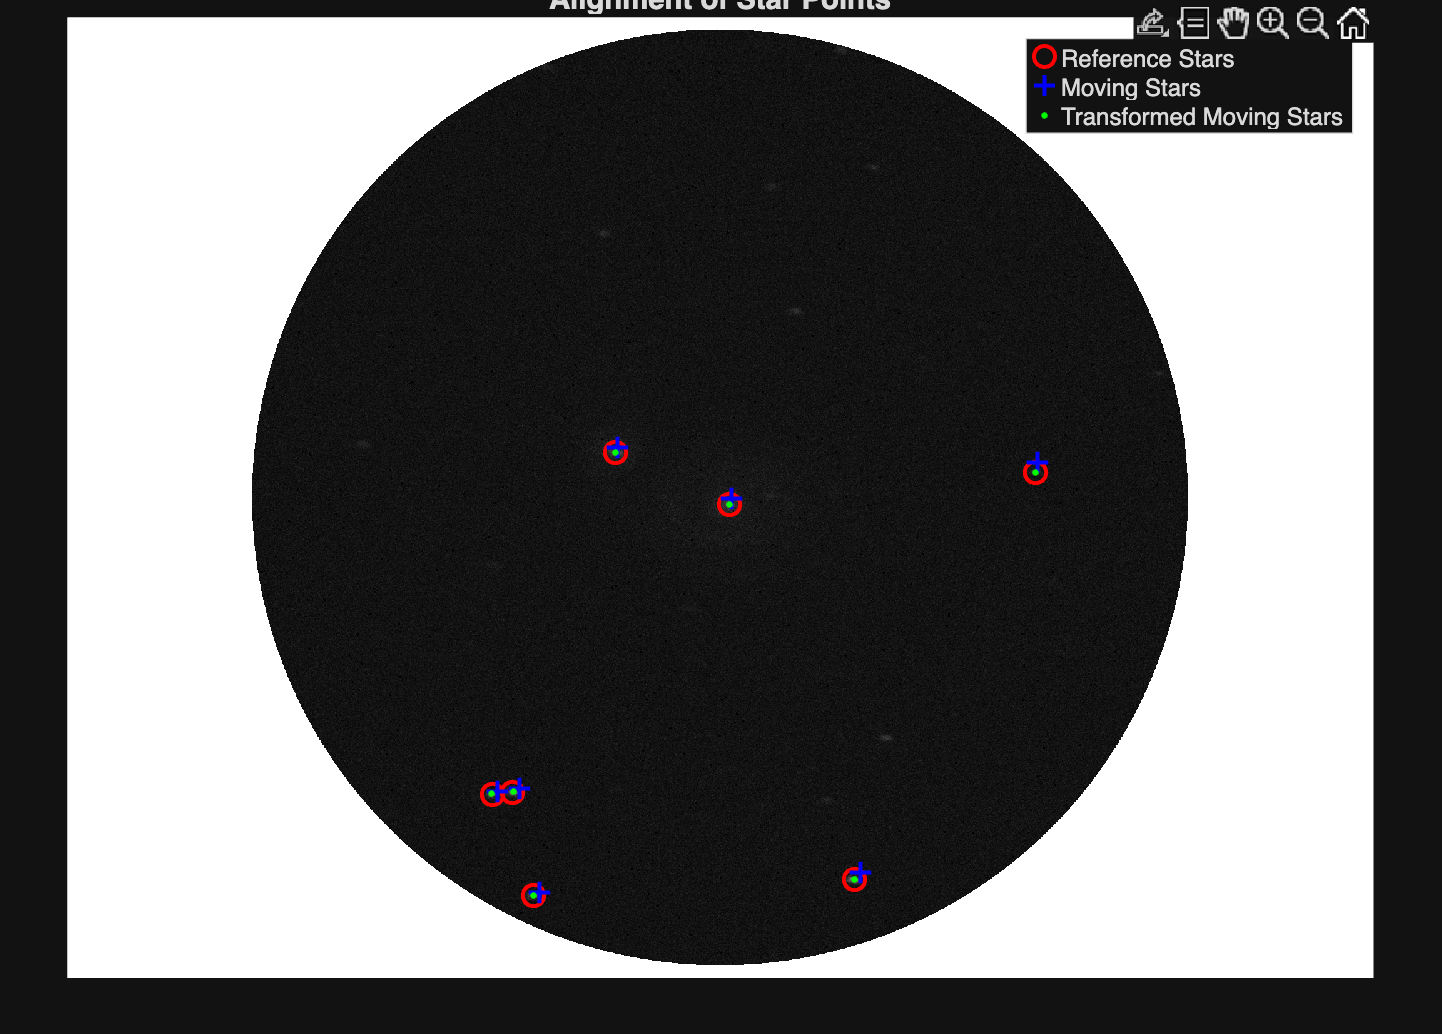

[rows, cols, ch] = size(i);
    
    % define center and radius
    center_x = cols/2;
    center_y = rows/2;
    radius = min(rows, cols)/2 - 20;
    
    % create grid of coordinates
    [x_grid, y_grid] = meshgrid(1:cols, 1:rows);
    
    % compute distance from center
    dist = sqrt((x_grid - center_x).^2 + (y_grid - center_y).^2);
    
    % create mask
    mask = dist <= radius;
    
    % apply mask to all channels
    img_cropped = i;
    if ch > 1
        mask3 = repmat(mask, [1 1 ch]);
        img_cropped(~mask3) = 1;
    else
        img_cropped(~mask) = 1;
    end
% plot
imshow(img_cropped); hold on;
plot(r_points(:,1), r_points(:,2), 'ro', 'MarkerSize', 8, 'LineWidth', 1.5);
plot(i_points(:,1), i_points(:,2), 'b+', 'MarkerSize', 8, 'LineWidth', 1.5);
plot(movingPointsTransformed(:,1), movingPointsTransformed(:,2), 'g*', 'MarkerSize', 2, 'LineWidth', 1.5);
legend('Reference Stars', 'Moving Stars', 'Transformed Moving Stars');
title('Alignment of Star Points');

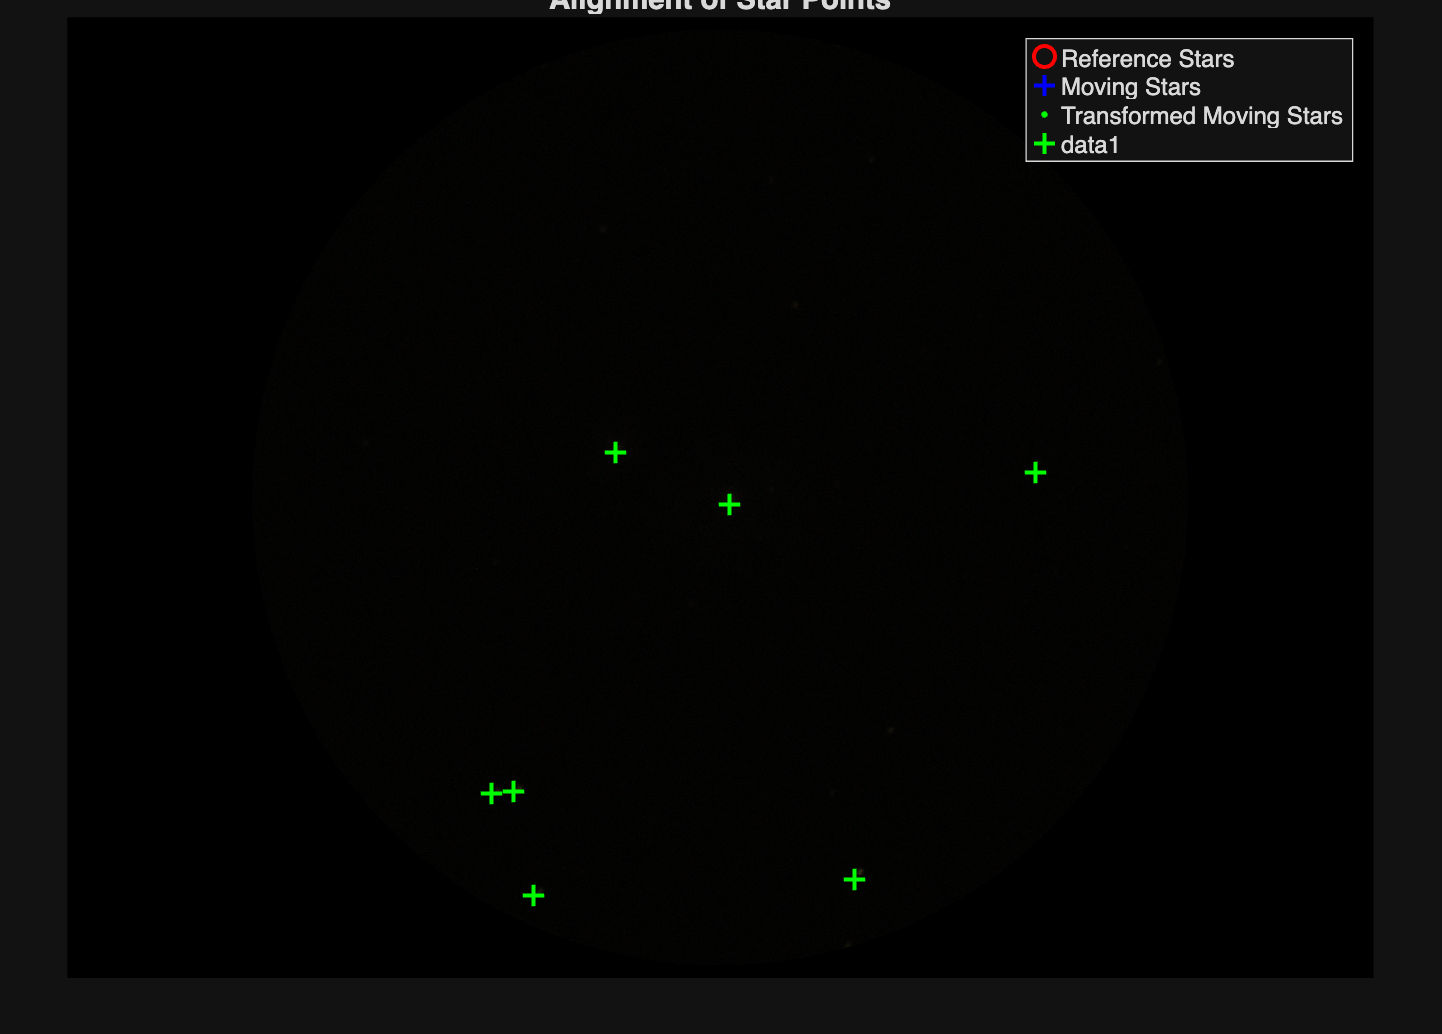

imshow(I)
plot(movingPointsTransformed(:,1), movingPointsTransformed(:,2), 'g+', 'MarkerSize', 8, 'LineWidth', 1.5);

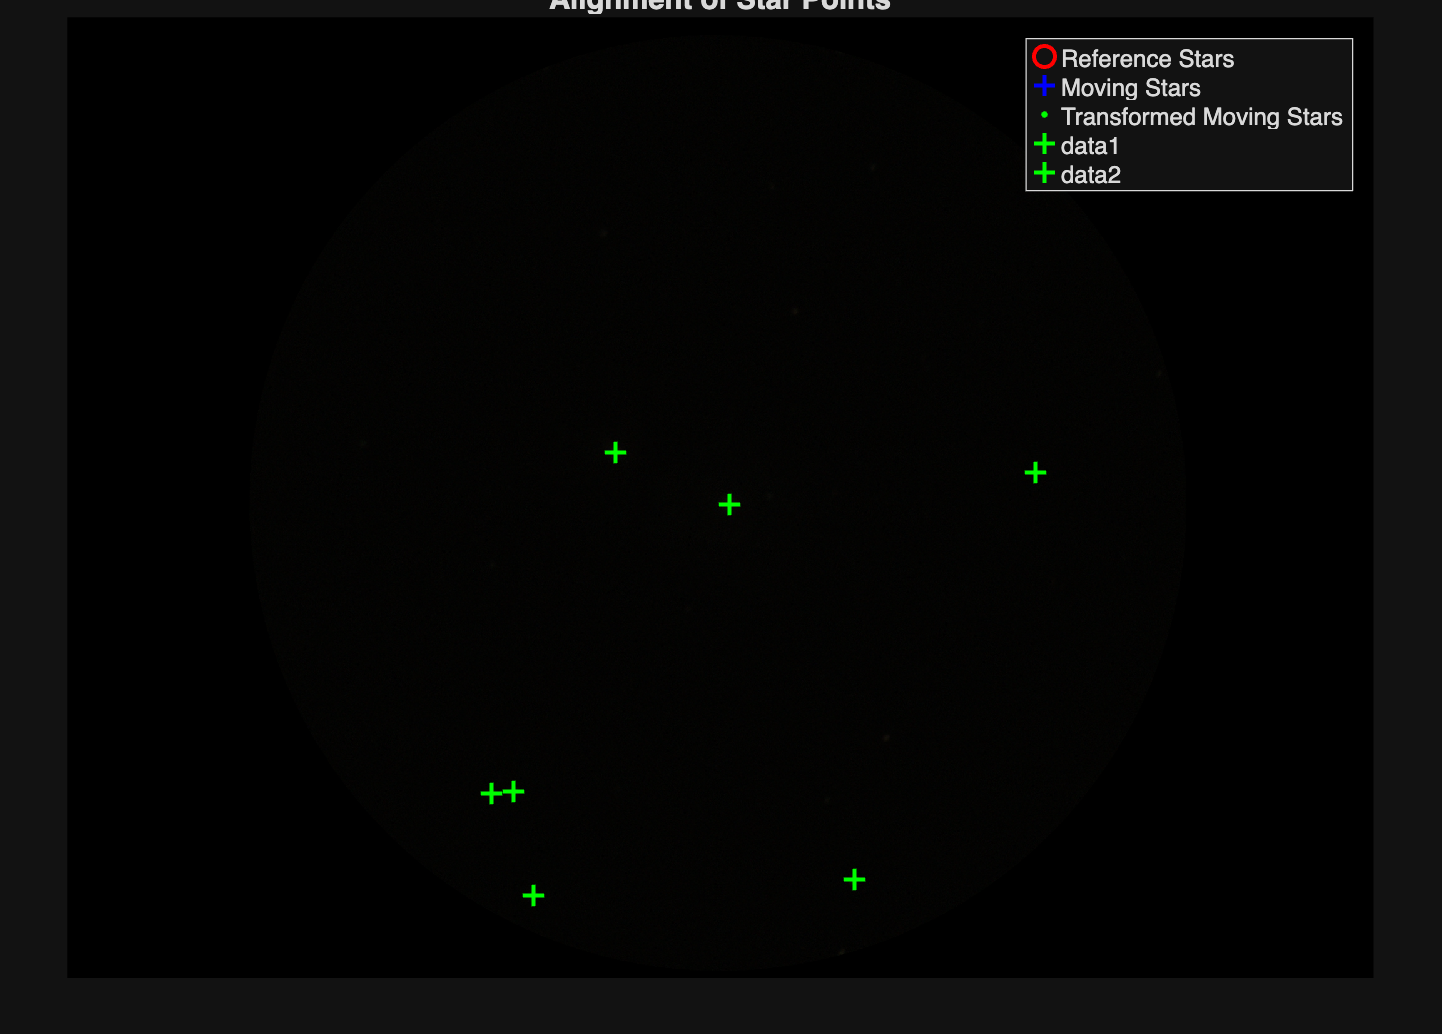

imshow(aligned)
plot(movingPointsTransformed(:,1), movingPointsTransformed(:,2), 'g+', 'MarkerSize', 8, 'LineWidth', 1.5);